camData = load('/home/prouse/HDD/photogrammetry/gopro_in_abyss/calibration/cameraParams.mat');
fisheyeParams = camData.cameraParams;imageDir = '/home/prouse/HDD/photogrammetry/gopro_in_abyss/pattern_office/close';
imds = imageDatastore(imageDir);
nimages = numel(imds.Files);
fisheyeIntrinsics = fisheyeParams.Intrinsics;
imagePoints = cell(1, nimages);
for i = 1:nimages
    [undistImage, camIntrinsics] = undistortFisheyeImage(readimage(imds, i), fisheyeIntrinsics);
    [imagePoints{i}, boardSize] = detectCheckerboardPoints(undistImage);
end

indexPairs = cell(nimages, nimages);
for i = 1:nimages
    for j = 1:(i-1)
        indexPairs{i,j} = repmat((1:54).', 1, 2);
    end
end

vSet = viewSet;
viewId = 1;
vSet = addView(vSet, viewId, 'Points', imagePoints{1}, 'Orientation', eye(3, 'like', imagePoints{1}), 'Location', zeros(1, 3, 'like', imagePoints{1}));

addpath '/home/prouse/Documents/MATLAB/Examples/R2019b/vision/StructureFromMotionFromMultipleViewsExample'

for i = 2:nimages
    [relativeOrient, relativeLoc, inlierIdx] = helperEstimateRelativePose(imagePoints{i-1}, imagePoints{i}, camIntrinsics);
    vSet = addView(vSet, i, 'Points', imagePoints{i});
    for j = 1:(i-1)
        vSet = addConnection(vSet, i, j, 'Matches', indexPairs{i,j});
    end
    prevPose = poses(vSet, i-1);
    prevOrientation = prevPose.Orientation{1};
    prevLocation    = prevPose.Location{1};
    orientation = relativeOrient * prevOrientation;
    location    = prevLocation + relativeLoc * prevOrientation;
    vSet = updateView(vSet, i, 'Orientation', orientation, 'Location', location);
    tracks = findTracks(vSet);
    camPoses = poses(vSet);
    xyzPoints = triangulateMultiview(tracks, camPoses, camIntrinsics);
    [xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(xyzPoints, tracks, camPoses, camIntrinsics, 'FixedViewId', 1, ...
        'PointsUndistorted', true, 'MaxIterations', 300, 'AbsoluteTolerance', 0.4, 'RelativeTolerance', 1e-8, 'Verbose', true);
    vSet = updateView(vSet, camPoses);
end

Initializing bundle adjustment solver ...
Starting Levenberg-Marquardt iterations:
Iteration 1:Mean squared reprojection error: 0.0046168
bundle adjustment stopped because the mean squared reprojection error was less than the specified absolute tolerance value.
Mean reprojection error before bundle adjustment: 0.053381.
Mean reprojection error after bundle adjustment: 0.053381.
Initializing bundle adjustment solver ...
Starting Levenberg-Marquardt iterations:
Iteration 1:Mean squared reprojection error: 534.8533
Iteration 2:Mean squared reprojection error: 44.152
Iteration 3:Mean squared reprojection error: 24.2209
Iteration 4:Mean squared reprojection error: 10.6988
Iteration 5:Mean squared reprojection error: 6.6266
Iteration 6:Mean squared reprojection error: 4.9594
Iteration 7:Mean squared reprojection error: 4.281
Iteration 8:Mean squared reprojection error: 4.2029
Iteration 9:Mean squared reprojection error: 3.6131
Iteration 10:Mean squared reprojection error: 3.387
Iteration 11:

vSet = updateView(vSet, camPoses);

truePoints = [ (mod(0:53,6)-2.5)' (floor((0:53)/6)-4)' zeros(54,1) ]*29.05;

% Find rotation matrix using Kabsch algorithm
translatedPoints = xyzPoints - mean(xyzPoints);
C=translatedPoints'*truePoints/size(truePoints,1);
[V,S,W] = svd(C);
I = eye(3);
if (det(V*W') < 0)
    I(3,3) = -1;
end
U = W*I*V';
scale = trace(S*I)/sum(var(translatedPoints));
transformedPoints = translatedPoints*U'*scale;
errors = transformedPoints - truePoints;

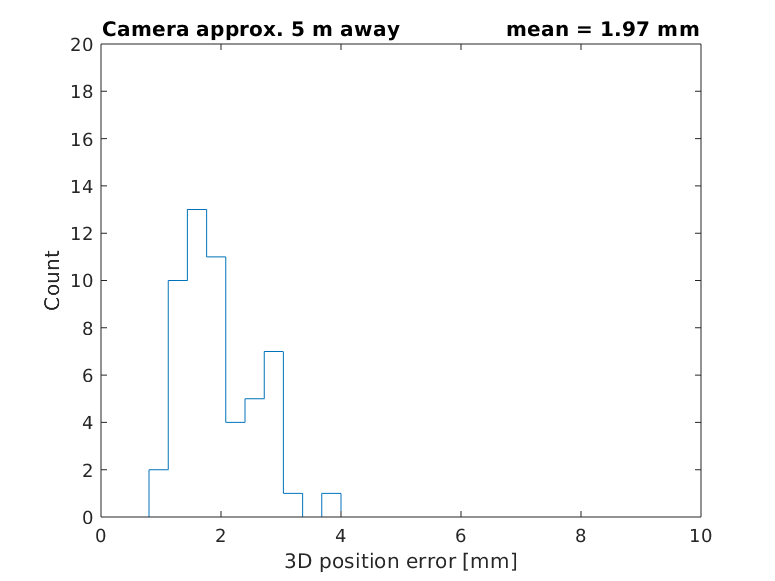

histogram(vecnorm(errors,2,2), 10,'DisplayStyle','stairs');
ylim([0 20]);
xlim([0 10]);
title(sprintf('Camera approx. 5 m away               mean = %.2f mm', mean(vecnorm(errors,2,2))));
ylabel('Count');
xlabel('3D position error [mm]');

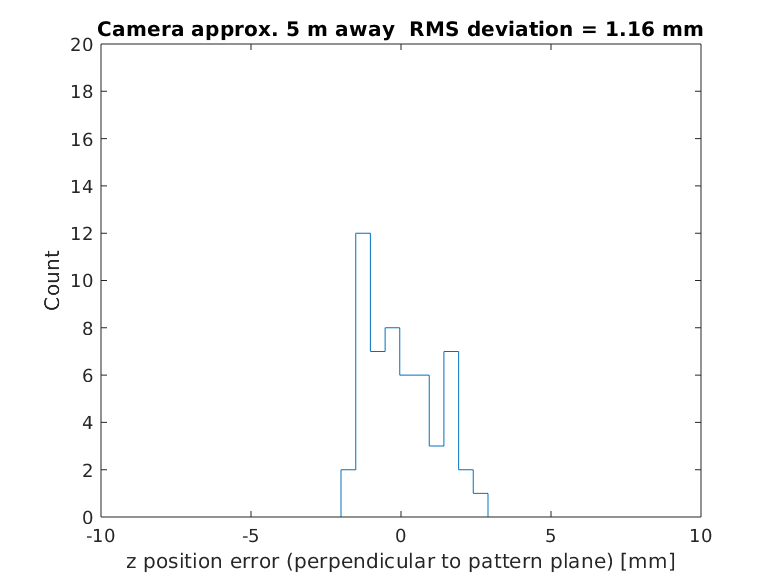

histogram(errors(:,3), 10,'DisplayStyle','stairs');
ylim([0 20]);
xlim([-10 10]);
title(sprintf('Camera approx. 5 m away  RMS deviation = %.2f mm', std(errors(:,3))));
ylabel('Count');
xlabel('z position error (perpendicular to pattern plane) [mm]');

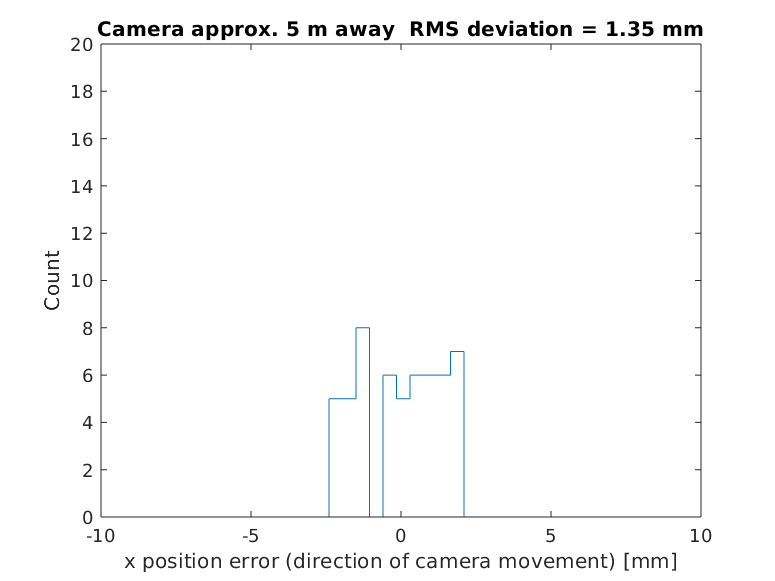

histogram(errors(:,2), 10,'DisplayStyle','stairs');
ylim([0 20]);
xlim([-10 10]);
title(sprintf('Camera approx. 5 m away  RMS deviation = %.2f mm', std(errors(:,2))));
ylabel('Count');
xlabel('x position error (direction of camera movement) [mm]');

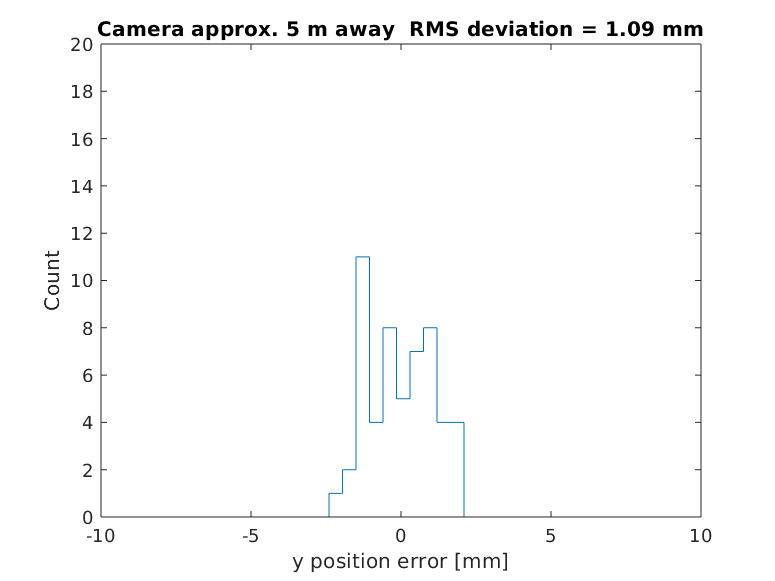

histogram(errors(:,1), 10,'DisplayStyle','stairs');
ylim([0 20]);
xlim([-10 10]);
title(sprintf('Camera approx. 5 m away  RMS deviation = %.2f mm', std(errors(:,1))));
ylabel('Count');
xlabel('y position error [mm]');

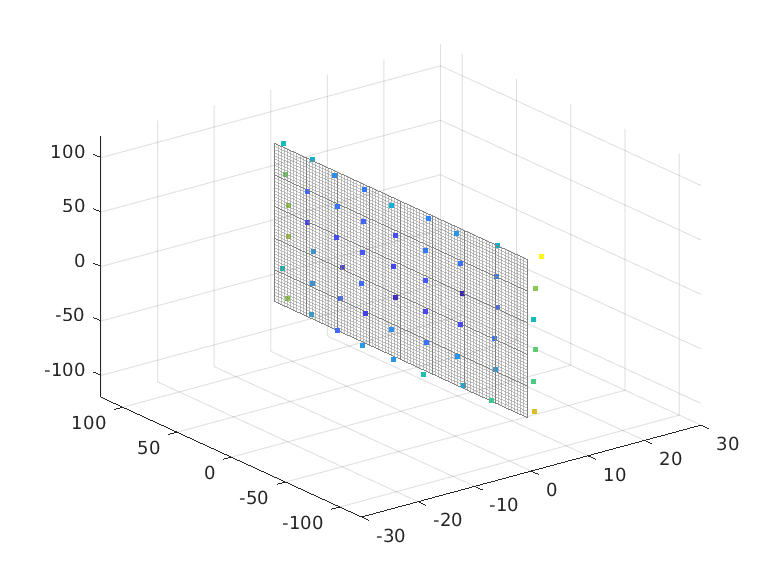

[X,Y] = meshgrid(linspace(-29.05*2.5,29.05*2.5,1+5), linspace(-29.05*4,29.05*4,1+8));
Z = zeros(size(X));
[X2,Y2] = meshgrid(linspace(-29.05*2.5,29.05*2.5,1+5*10), linspace(-29.05*4,29.05*4,1+8*10));
Z2 = zeros(size(X2));
figure(1)
scatter3(transformedPoints(:,3),transformedPoints(:,2),transformedPoints(:,1),ones(size(transformedPoints(:,3)))*30,vecnorm(errors,2,2),"filled")
a = get(gca,'Clim');
hold on
mesh(Z, Y, X, 'LineStyle', '-', 'FaceColor', 'none', 'EdgeColor', [0.5 0.5 0.5])
mesh(Z2, Y2, X2, 'LineStyle', '-', 'FaceColor', 'none', 'EdgeColor', [0.5 0.5 0.5], 'EdgeAlpha', 0.5)
%plot3(transformedPoints(:,1),transformedPoints(:,2),transformedPoints(:,3),'.')
xlim([-30, 30])
ylim([-120 120])
zlim([-120 120])
set(gca,'Clim',a);
hold off

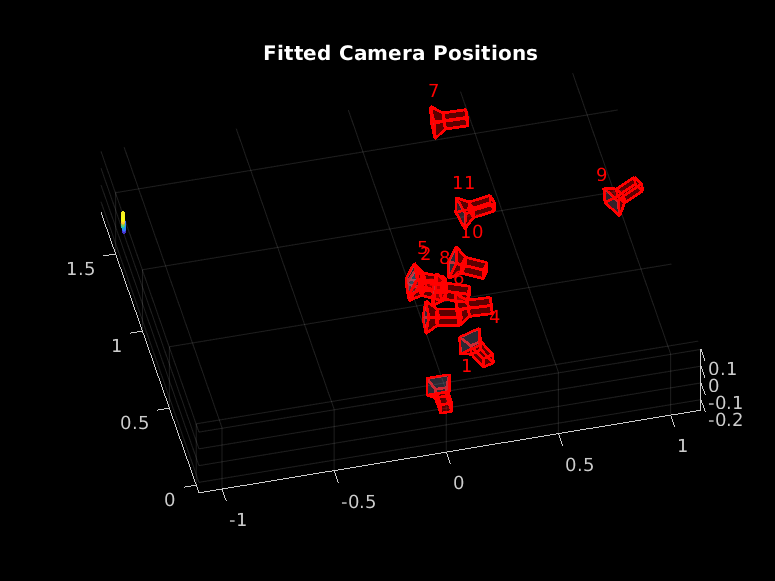

% Display camera poses.
camPoses = poses(vSet);
figure;
plotCamera(camPoses, 'Size', 0.05);
hold on

% Display the 3-D points.
pcshow(xyzPoints, 'MarkerSize', 45, 'VerticalAxis', 'y', 'VerticalAxisDir', 'up');

grid on
hold off

% Specify the viewing volume.
%loc1 = camPoses.Location{1};
%xlim([loc1(1)-5, loc1(1)+4]);
%ylim([loc1(2)-5, loc1(2)+4]);
%zlim([loc1(3)-1, loc1(3)+20]);
%camorbit(0, -30);

title('Fitted Camera Positions');

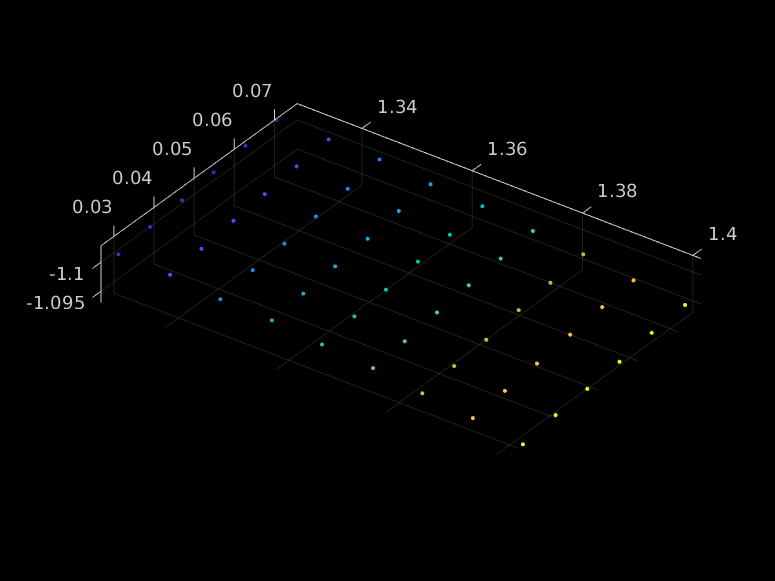

pcshow(xyzPoints, 'MarkerSize', 45, 'VerticalAxis', 'x', 'VerticalAxisDir', 'down');